# Creat Grid Map

`@author: Winter`

`@update: 2023.1.29`

## function import

addpath("env\");

## map A

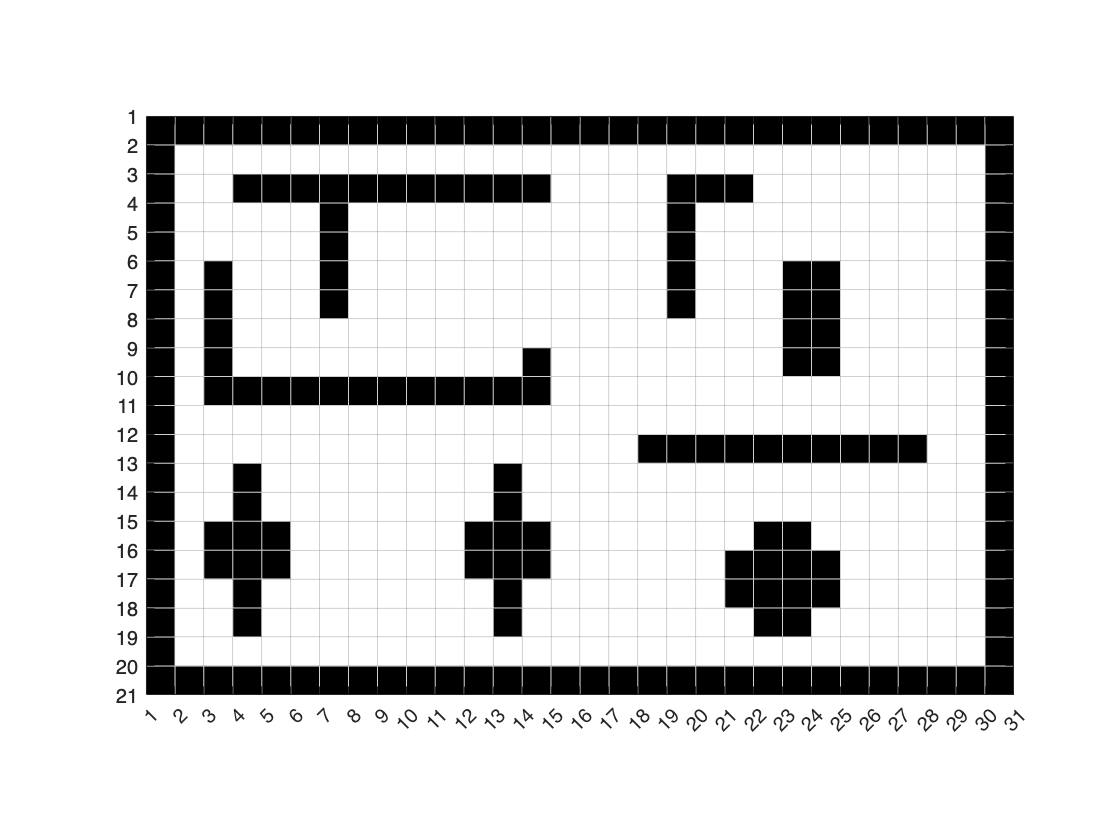

clear all;
clc;

% map setting
map_size = [20, 30];
G = 1;

% obstacle
obs0 = [1:map_size(1), ... 
        map_size(1):map_size(1):map_size(1) * map_size(2), ...
        1:map_size(1):(map_size(1) - 1) * map_size(2), ...
        map_size(1) * (map_size(2) - 1):map_size(1) * map_size(2)];
obs1 = [63, 83, 103, 123, 143, 163, 183, 203, 223, 243, 263, 124, 125, 126, 127];
obs2 = [46, 47, 48, 49, 50, 70, 90, 110, 130, 150, 170, 190, 210, 230, 250, 270, 269];
obs3 = [73, 74, 55, 75, 95, 56, 76, 96, 77, 78];
obs4 = [253, 254, 235, 255, 275, 236, 256, 276, 257, 258];
obs5 = [352, 372, 392, 412, 432, 452, 472, 492, 512, 532];
obs6 = [435, 416, 436, 417, 437, 438, 455, 456, 476, 457, 477, 458];
obs7 = [363, 364, 365, 366, 367, 383, 403];
obs8 = [446, 447, 448, 449, 466, 467, 468, 469];
obstacle = [obs0, obs1, obs2, obs3, obs4, obs5, obs6, obs7, obs8];

% creat grid
grid_map = generate_grid(map_size, obstacle);

% save and plot
% save gridmap_20x20_scene1 grid_map
plot_grid(grid_map);

## map B

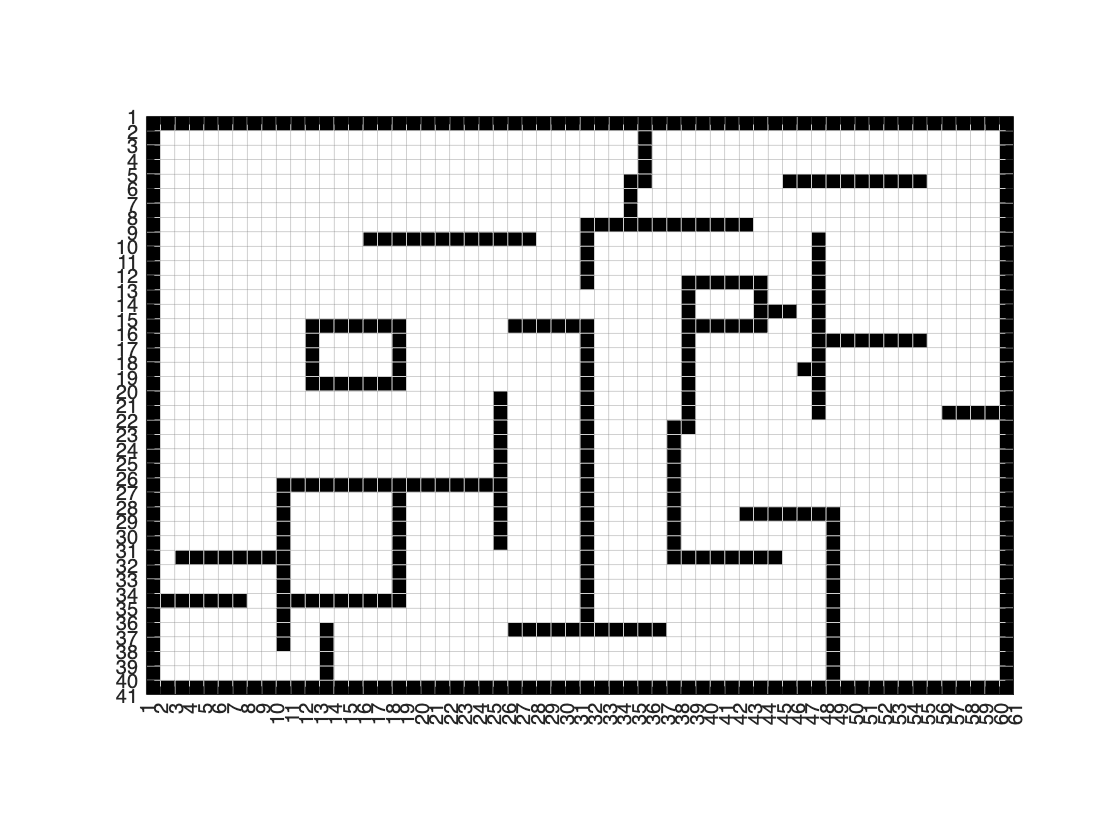

clear all;
clc;

% map setting
map_size = [40, 60];
G = 1;

% obstacle
obstacle = [40, 80, 120, 160, 200, 240, 280, 320, 360, 400, 440, 480, 520, 560, 600, 640, 680, 720, 760, 800, 840, 880, 920, 960, 1000, 1040, 1080, 1120, 1160, 1200, 1240, 1280, 1320, 1360, 1400, 1440, 1480, 1520, 1560, 1600, 1640, 1680, 1720, 1760, 1800, 1840, 1880, 1920, 1960, 2000, 2040, 2080, 2120, 2160, 2200, 2240, 2280, 2320, 2360, 2400, 39, 519, 1919, 2399, 38, 518, 1918, 2398, 37, 397, 517, 1917, 2397, 36, 396, 516, 1036, 1076, 1116, 1156, 1196, 1236, 1276, 1316, 1356, 1396, 1436, 1916, 2396, 35, 395, 1235, 1915, 2395, 34, 74, 114, 154, 194, 234, 274, 394, 434, 474, 514, 554, 594, 634, 674, 714, 1234, 1914, 2394, 33, 393, 713, 1233, 1913, 2393, 32, 392, 712, 1232, 1912, 2392, 31, 111, 151, 191, 231, 271, 311, 351, 391, 711, 1231, 1471, 1511, 1551, 1591, 1631, 1671, 1711, 1751, 1911, 2391, 30, 390, 710, 990, 1230, 1470, 1910, 2390, 29, 389, 709, 989, 1229, 1469, 1909, 2389, 28, 388, 708, 988, 1228, 1468, 1668, 1708, 1748, 1788, 1828, 1868, 1908, 2388, 27, 387, 707, 987, 1227, 1467, 2387, 26, 386, 426, 466, 506, 546, 586, 626, 666, 706, 746, 786, 826, 866, 906, 946, 986, 1226, 1466, 2386, 25, 985, 1225, 1465, 2385, 24, 984, 1224, 1464, 2384, 23, 983, 1223, 1463, 2383, 22, 982, 1222, 1462, 1502, 2382, 21, 981, 1221, 1501, 1861, 2221, 2261, 2301, 2341, 2381, 20, 980, 1220, 1500, 1860, 2380, 19, 459, 499, 539, 579, 619, 659, 699, 1219, 1499, 1859, 2379, 18, 458, 698, 1218, 1498, 1818, 1858, 2378, 17, 457, 697, 1217, 1497, 1857, 2377, 16, 456, 696, 1216, 1496, 1856, 1896, 1936, 1976, 2016, 2056, 2096, 2136, 2376, 15, 455, 495, 535, 575, 615, 655, 695, 1015, 1055, 1095, 1135, 1175, 1215, 1495, 1535, 1575, 1615, 1655, 1695, 1855, 2375, 14, 1494, 1694, 1734, 1774, 1854, 2374, 13, 1493, 1693, 1853, 2373, 12, 1212, 1492, 1532, 1572, 1612, 1652, 1692, 1852, 2372, 11, 1211, 1851, 2371, 10, 1210, 1850, 2370, 9, 609, 649, 689, 729, 769, 809, 849, 889, 929, 969, 1009, 1049, 1209, 1849, 2369, 8, 1208, 1248, 1288, 1328, 1368, 1408, 1448, 1488, 1528, 1568, 1608, 1648, 2368, 7, 1327, 2367, 6, 1326, 2366, 5, 1325, 1365, 1765, 1805, 1845, 1885, 1925, 1965, 2005, 2045, 2085, 2125, 2365, 4, 1364, 2364, 3, 1363, 2363, 2, 1362, 2362, 1, 41, 81, 121, 161, 201, 241, 281, 321, 361, 401, 441, 481, 521, 561, 601, 641, 681, 721, 761, 801, 841, 881, 921, 961, 1001, 1041, 1081, 1121, 1161, 1201, 1241, 1281, 1321, 1361, 1401, 1441, 1481, 1521, 1561, 1601, 1641, 1681, 1721, 1761, 1801, 1841, 1881, 1921, 1961, 2001, 2041, 2081, 2121, 2161, 2201, 2241, 2281, 2321, 2361];
    
% creat grid
grid_map = generate_grid(map_size, obstacle);

% save and plot
save gridmap_40x60_city1 grid_map
plot_grid(grid_map);

## map C

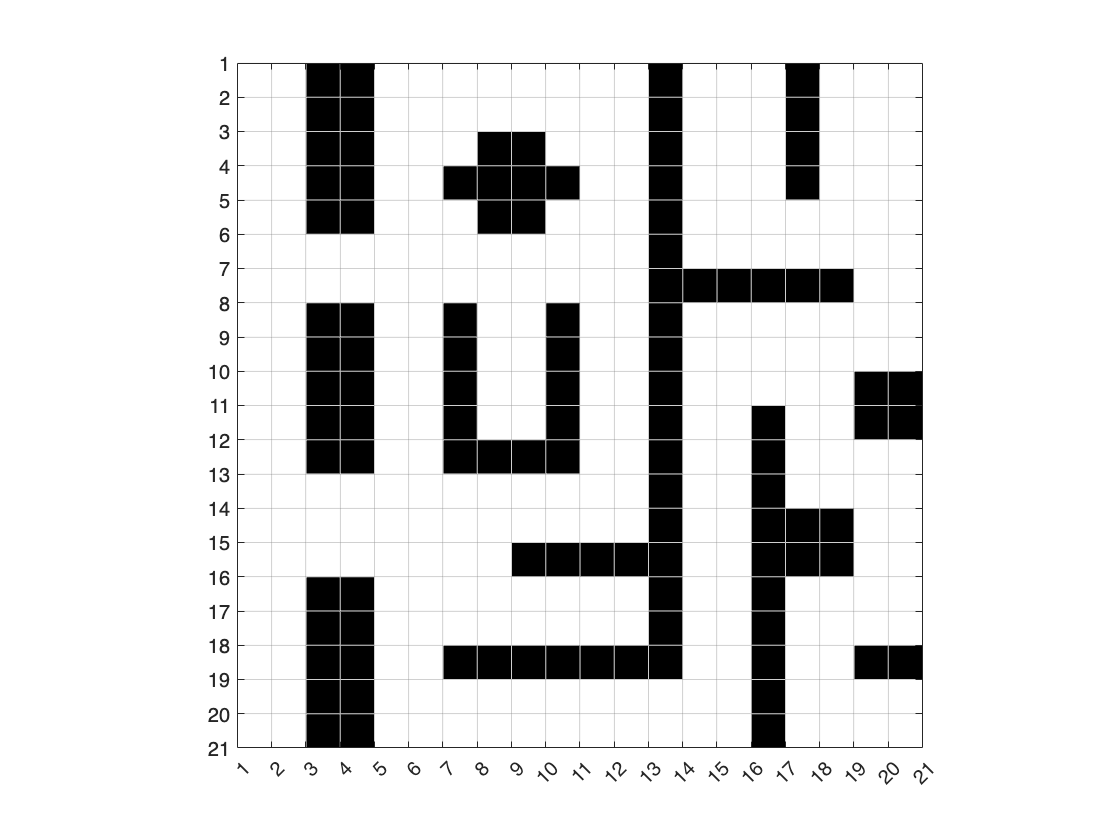

clear all;
clc;

% map setting
map_size = [20, 20];
G = 1;    

% obstacle
obs1 = [56, 57, 58, 59, 60, 76, 77, 78, 79, 80];
obs2 = [241, 242, 243, 244, 245, 246, 247, 248, 249, 250, 251, 252, 253, 254, 255, 256, 257, 258];
obs3 = [128, 129, 130, 131, 132, 152, 172, 192, 191, 190, 189, 188];
obs4 = [311, 312, 313, 314, 315, 316, 317, 318, 319, 320];
obs5 = [138, 158, 178, 198, 218, 238, 175, 195, 215, 235, 255];
obs6 = [124, 144, 164, 184, 143, 163, 145, 165];
obs7 = [267, 287, 307, 327, 347, 321, 322, 323, 324];
obs8 = [370, 390, 371, 391, 334, 354, 335, 354, 355, 378, 398];
obstacle = [obs1, obs1- 8, obs1 - 15, obs2, obs3, obs4, obs5, obs6, obs7, obs8];
    
% creat grid
grid_map = generate_grid(map_size, obstacle);

% save and plot
% save gridmap_20x20_scene3 grid_map
plot_grid(grid_map);

## map D

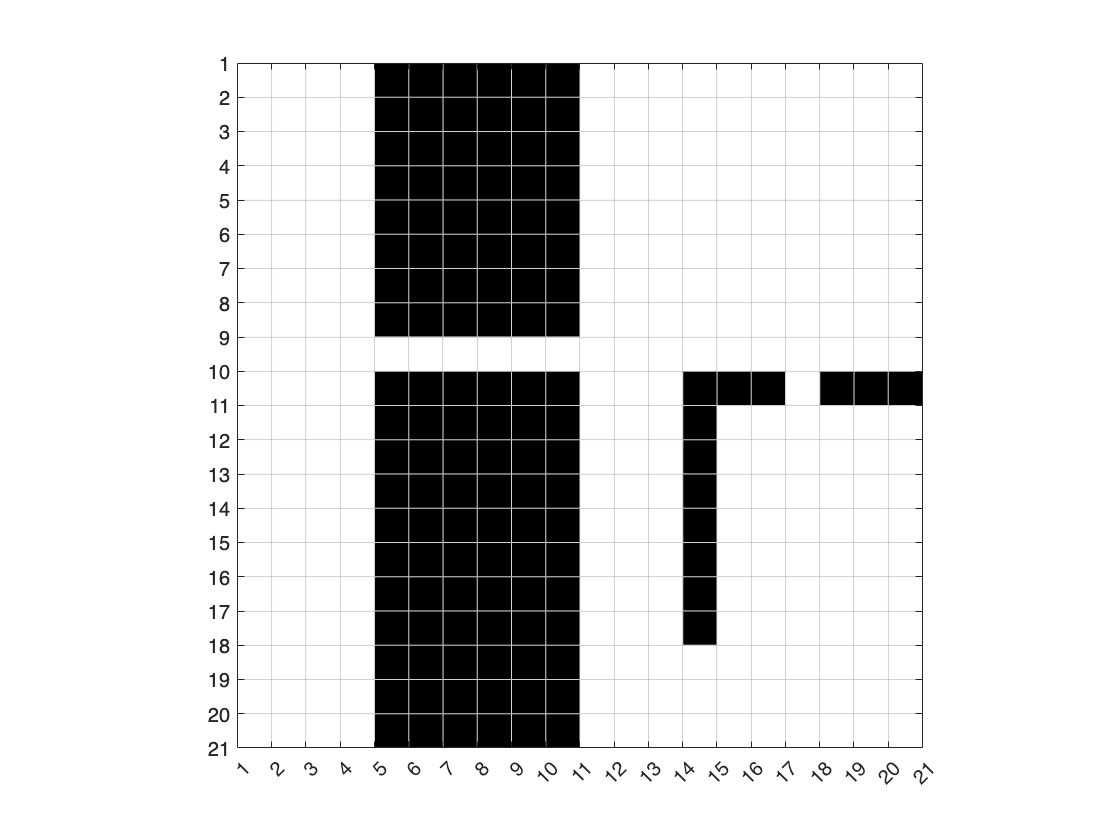

clear all;
clc;

% map setting
map_size = [20, 20];
G = 1; 

% obstacle
obs1 = 81:88;
obs2 = 90:100;
obs3 = 270:277;
obs4 = [290, 310, 350, 370, 390];

obstacle = [obs1, obs2, obs1 + 20, obs2 + 20, obs1 + 40, obs2 + 40, obs1 + 60, obs2 + 60, obs1 + 80, obs2 + 80, ...
    obs1 + 100, obs2 + 100, obs3, obs4];

% creat grid
grid_map = generate_grid(map_size, obstacle);

% save and plot
% save gridmap_20x20_scene4 grid_map
plot_grid(grid_map);

## 测试

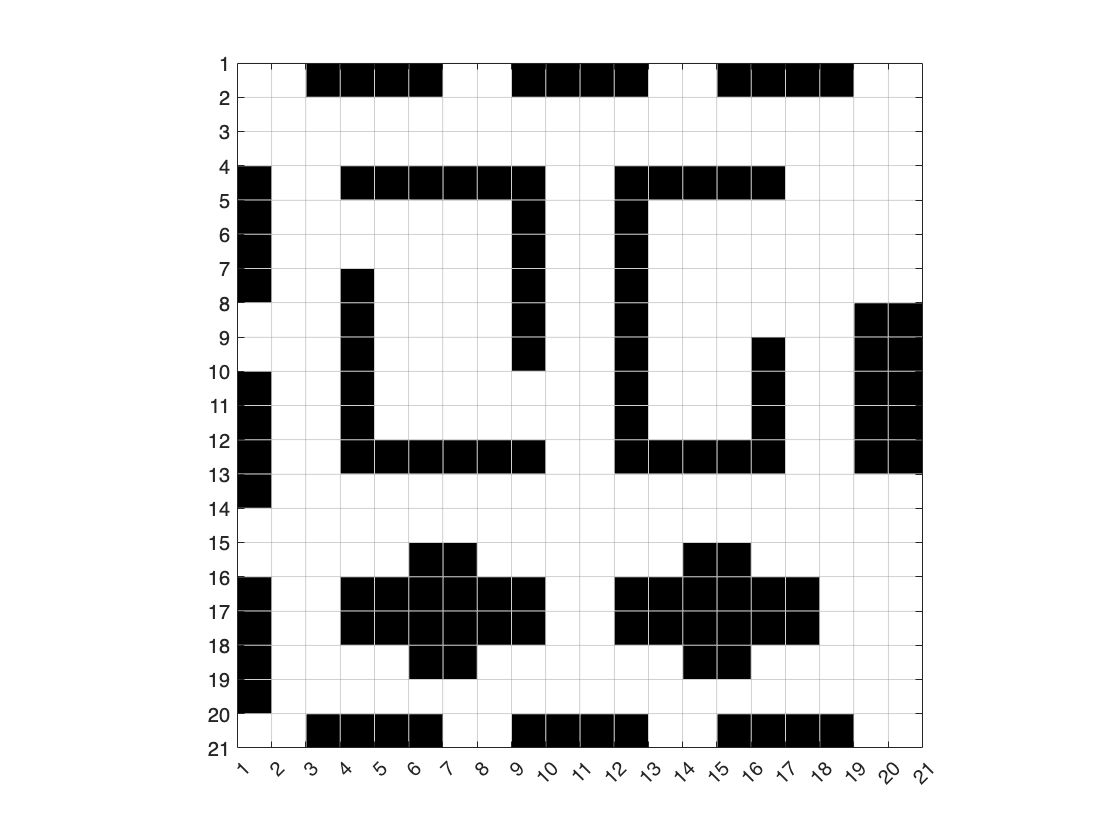

clear all;
clc;

% map setting
map_size = [20, 20];
G = 1; 

% obstacle
obs1 = 4:7;
obs2 = [41, 61, 81, 101];
obs3 = 368:372;
obs4 = [64,84, 104, 124, 144, 164, 165, 166, 167, 168, 169];
obs5 = [67, 68, 69, 70, 71, 72, 92, 112, 132, 152, 172];
obs6 = [76, 77, 96, 97, 115, 116, 117, 118, 135, 136, 137, 138, 156, 157, 176, 177];
obs7 = [224, 225, 226, 227, 228, 229, 230, 231, 232, 244, 264, 284, 304, 252, 272, 292, 312, 311, 310, 309];

obstacle = [obs1, obs1 + 6, obs1 + 12, obs2, obs2 + 120, obs2 + 240, obs2 + 19,...
            obs2 + 139, obs2 + 259, obs3, obs3 + 20, obs4, obs5, obs6, obs6 + 160, obs7];

% creat grid
grid_map = generate_grid(map_size, obstacle);

% save and plot
% save gridmap_20x20_scene4 grid_map
plot_grid(grid_map);

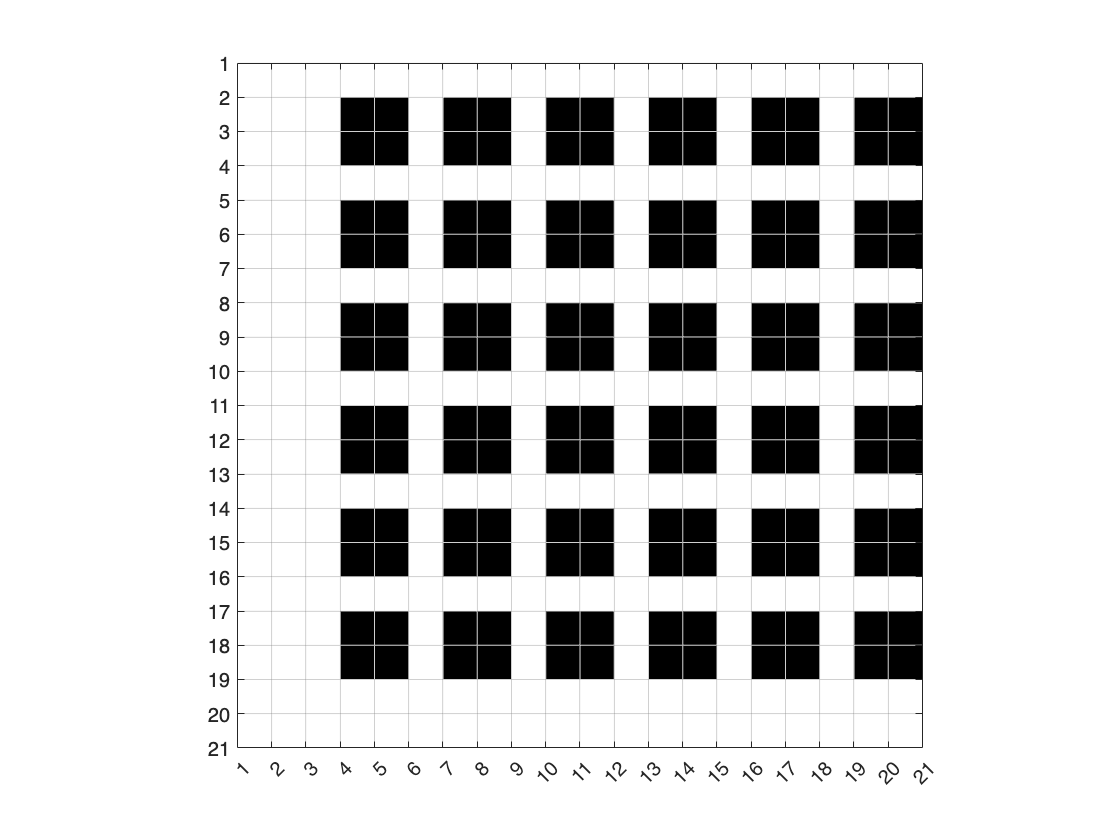

clear all;
clc;

% map setting
map_size = [20, 20];
G = 1; 

% obstacle
obs = [62, 63, 82, 83];
obstacle = [];
for i=0:5
    for j=0:5
        obs_ = obs + 60 * i + 3 * j;
        obstacle = [obstacle, obs_];
    end
end
% obstacle = [obs, obs + 60];

% creat grid
grid_map = generate_grid(map_size, obstacle);

% save and plot
% save gridmap_20x20_scene4 grid_map
plot_grid(grid_map);